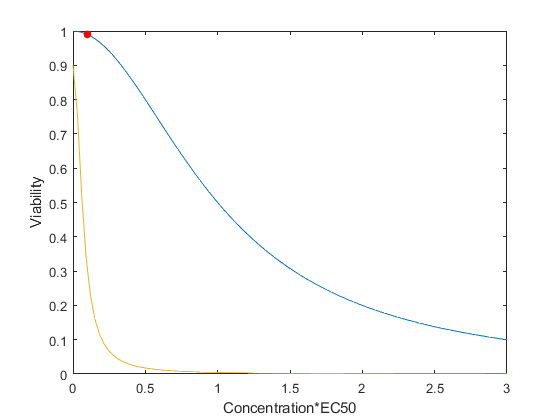

x1 = linspace(0,3,100);
E1 = 0;
h1 = 2;
E0 = 1;
C1 = 1;

E2 = 0.5;
h2 = 2;
C2 = 1;

coeff1 = [E1, h1, E0, C1];
coeff2 = [E2, h2, E0, C2];

alpha = 1.5; % log
alpha12 = 10^alpha;
alpha21 = 10^alpha;

E3 = 0;

r1 = 1;
r2 = 1;

x2 = 0.5.*ones(1,100);

y2 = MuSyC2([E1, h1, E0, C1, E2, h2, C2, alpha12, alpha21, E3, r1, r2], x1, x2);


y = MuSyC1(coeff1, x1);

plot(x1,y)
axis([0 3 0 1])
xlabel('Concentration*EC50')
ylabel('Viability')

cutoff = 0.1; % percent
ycutoff = MuSyC1(coeff1, cutoff);
hold on
plot(cutoff, ycutoff, '.r', 'MarkerSize', 20)


% Plot for 2 drugs
plot(x1, y2)
hold off